# Diffraction Experiment

Author: Peter_H

## initialize

x=linspace(-10,10,500);
y=linspace(-10,10,500);
% C=x.*y;
[xx,yy]=meshgrid(x,y);

## Single Slit

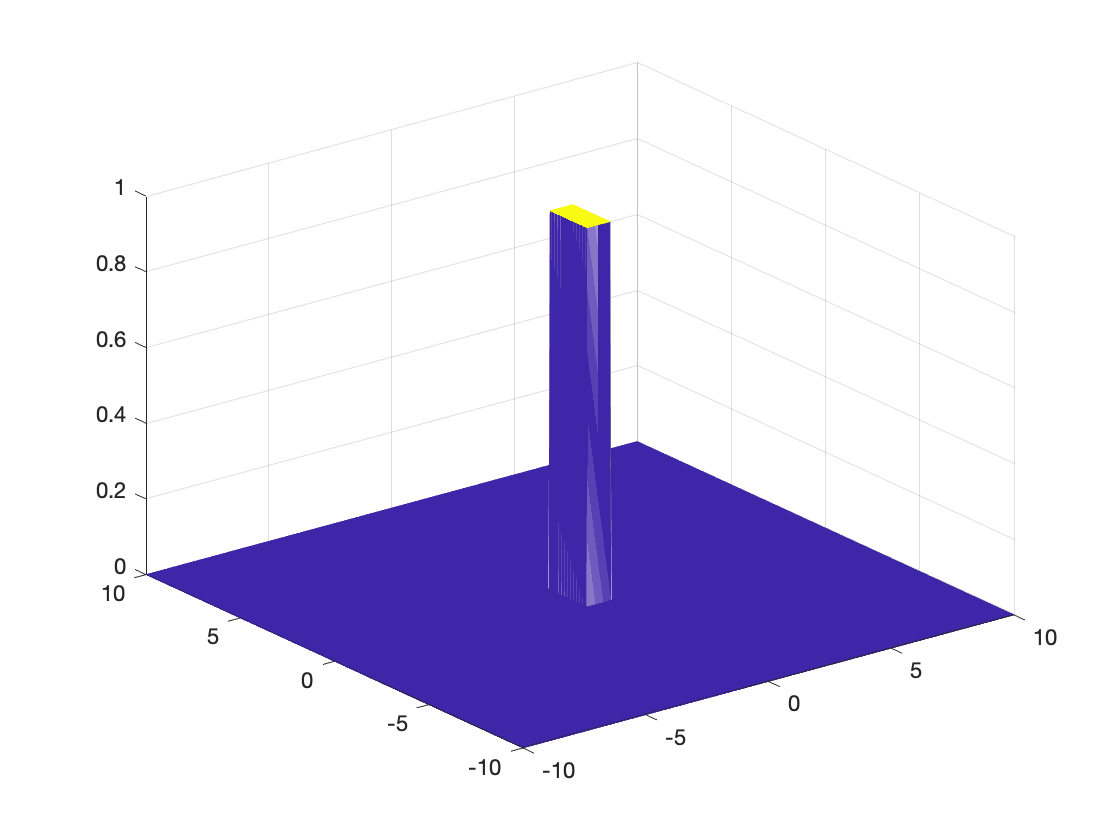

a=1;b=2;
rect=(xx>-a/2)&(xx<a/2)&(yy>-b/2)&(yy<b/2);
I=abs(fftshift(fft2(rect)));
figure;
mesh(xx,yy,rect);

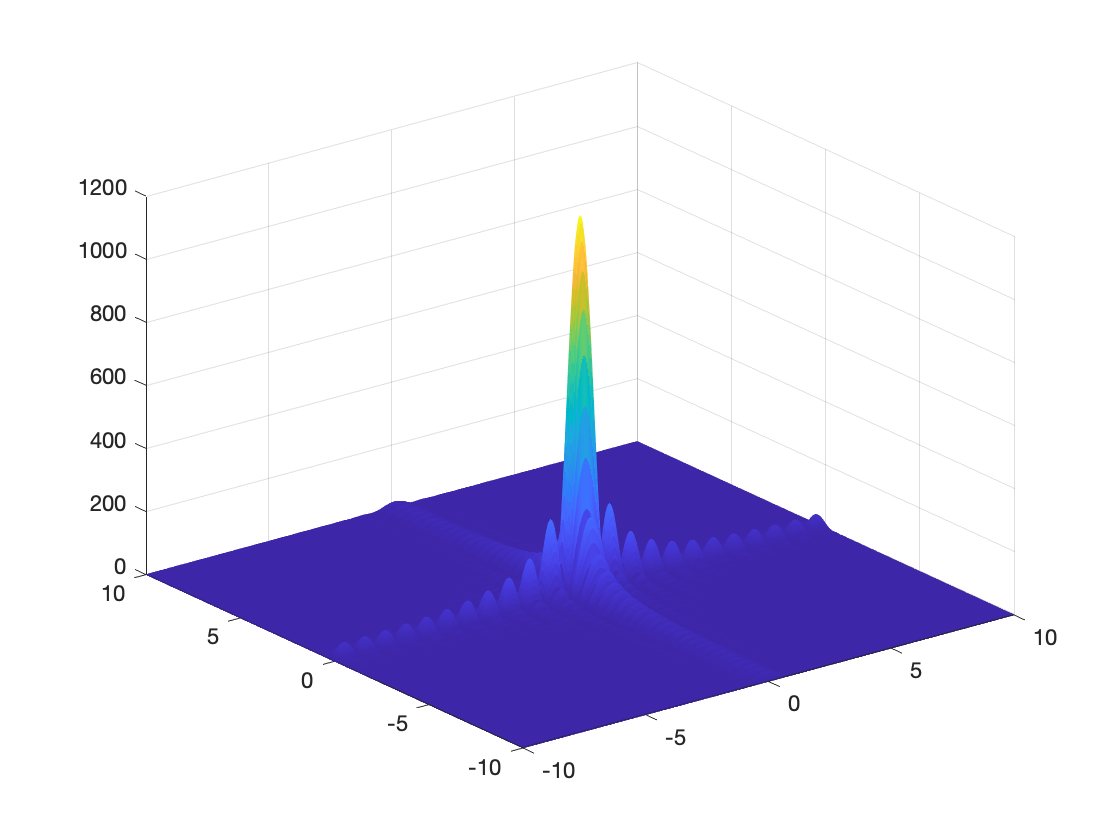

figure;
surf(xx,yy,I,'EdgeColor',"flat",'FaceColor',"flat");

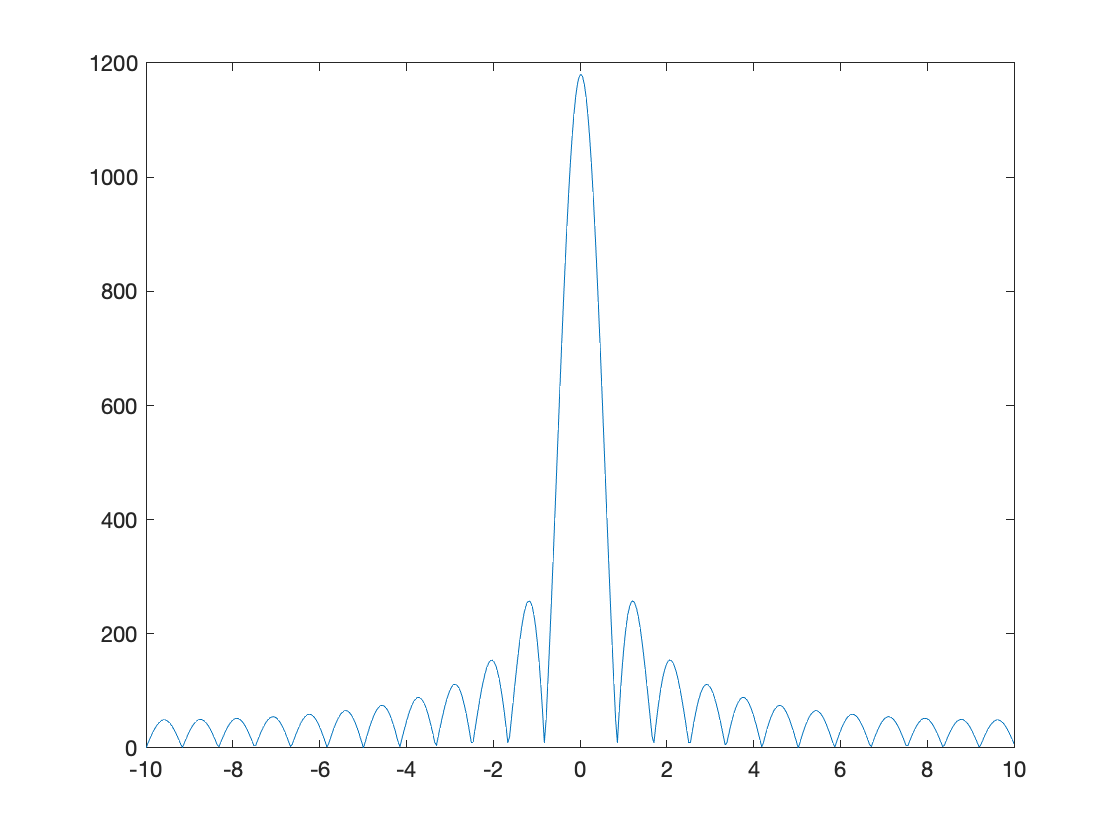

figure;
plot(x,I(floor(length(xx)/2),:));

## Double Slit

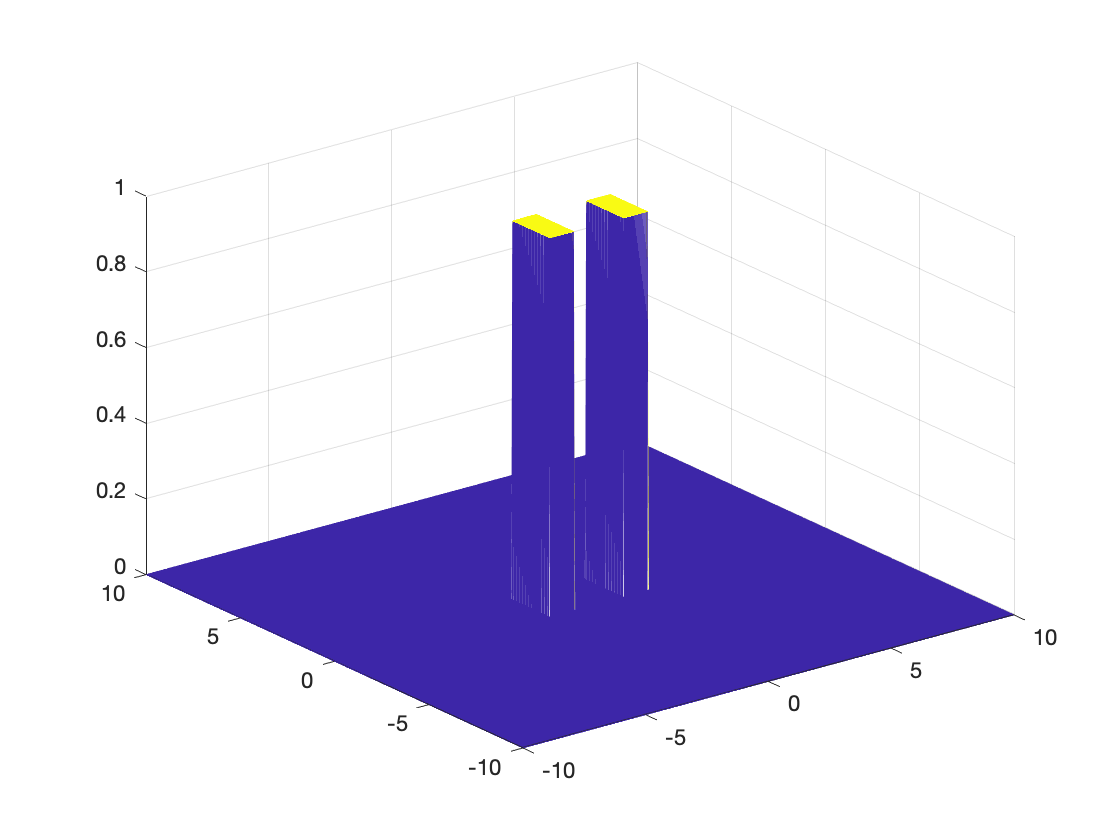

a1=1;b1=2;
a2=1;b2=2;
d=3;
rect1=(xx>-a1/2-d/2)&(xx<a1/2-d/2)...
    &(yy>-b1/2)&(yy<b1/2);
rect2=(xx>-a2/2+d/2)&(xx<a2/2+d/2)...
    &(yy>-b2/2)&(yy<b2/2);
drect=rect1|rect2;
I=abs(fftshift(fft2(drect)));
figure;
mesh(xx,yy,drect);

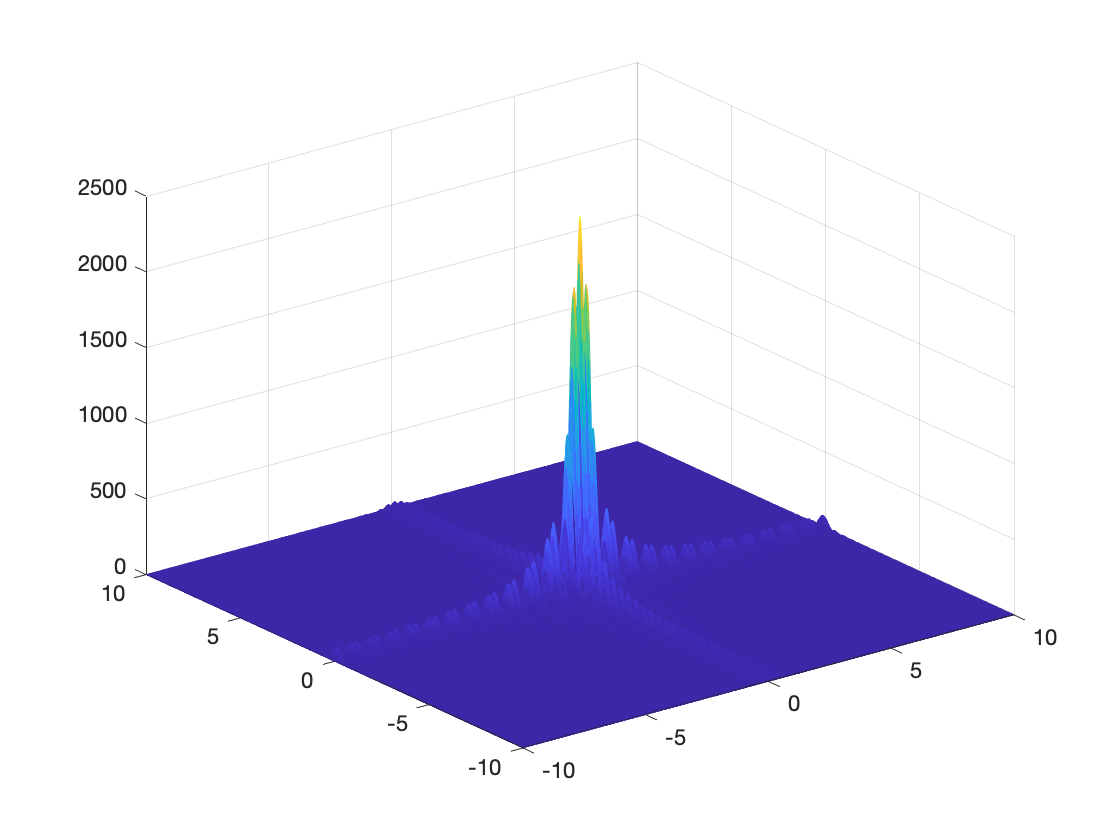

figure;
surf(xx,yy,I,'EdgeColor',"flat",'FaceColor',"flat");

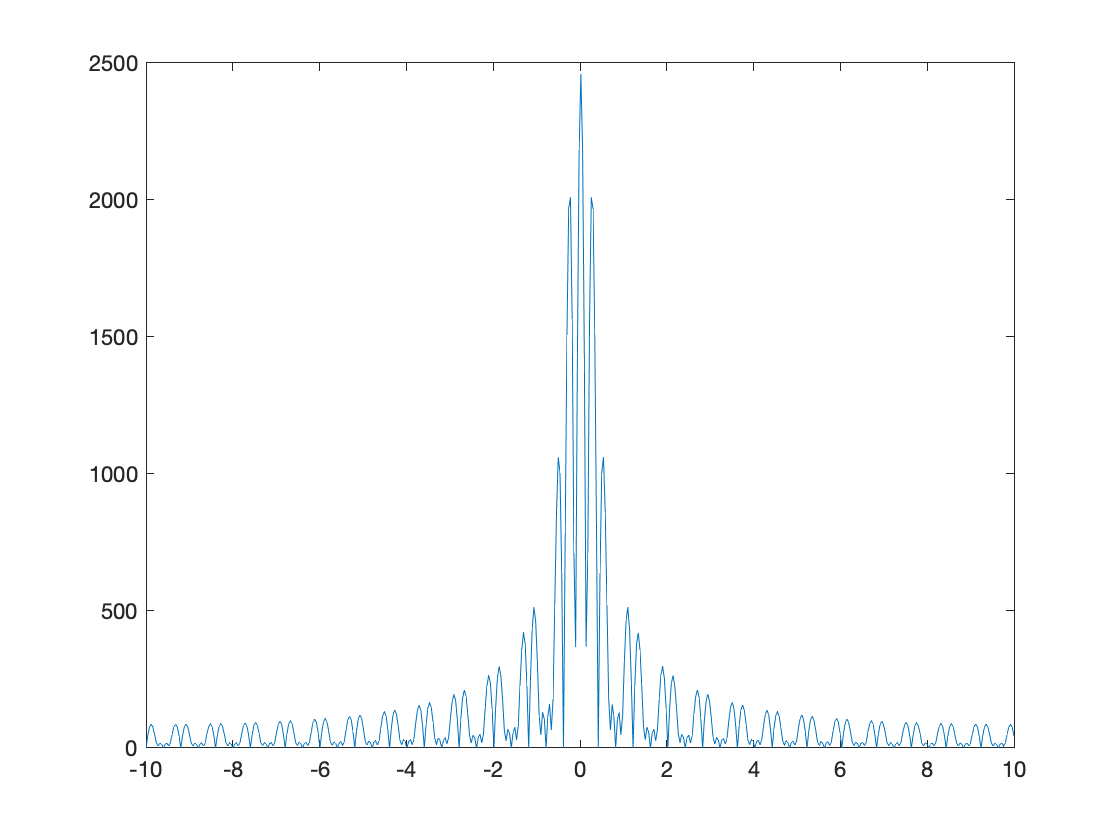

figure;
plot(x,I(length(xx)/2,:));

## Three Slit

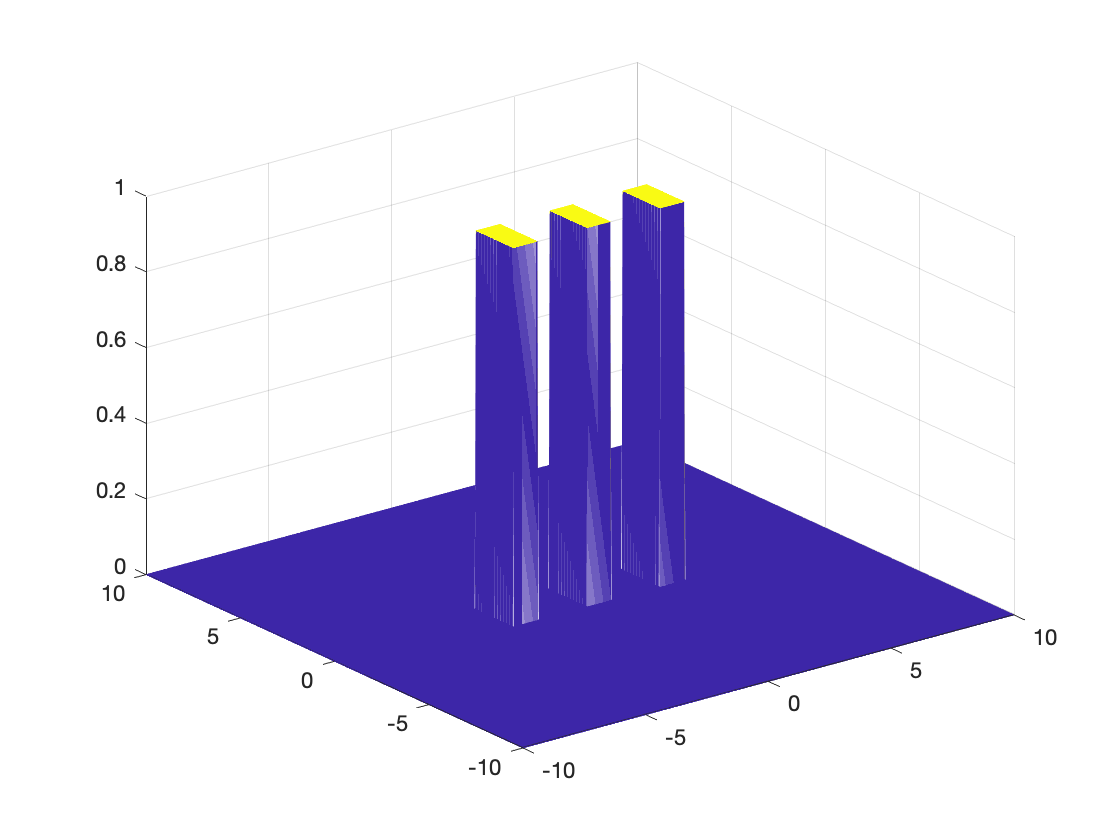

a=1;b=2;
d=3;
rect1=(xx>-a/2)&(xx<a/2)&(yy>-b/2)&(yy<b/2);
rect2=(xx>-a/2-d)&(xx<a/2-d)&(yy>-b/2)&(yy<b/2);
rect3=(xx>-a/2+d)&(xx<a/2+d)&(yy>-b/2)&(yy<b/2);
trirect=rect1|rect2|rect3;
I=abs(fftshift(fft2(trirect)));
figure;
mesh(xx,yy,trirect);

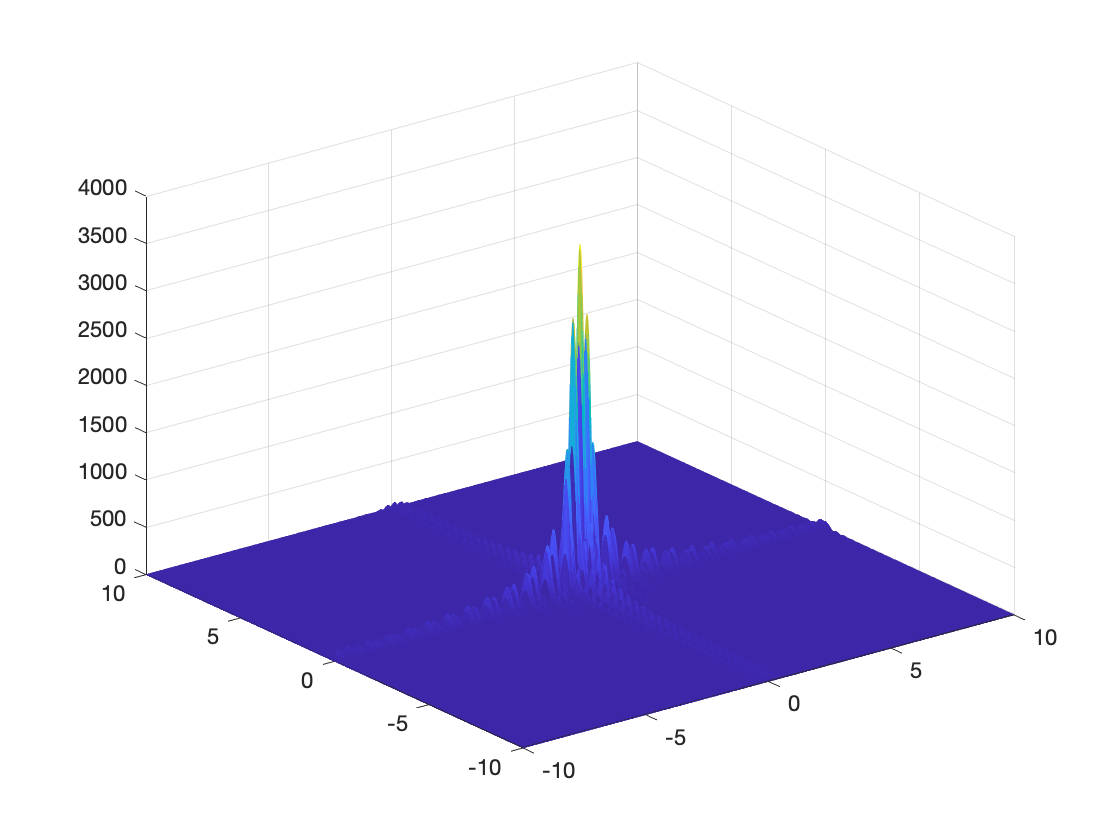

figure;
surf(xx,yy,I,'EdgeColor',"flat",'FaceColor',"flat");

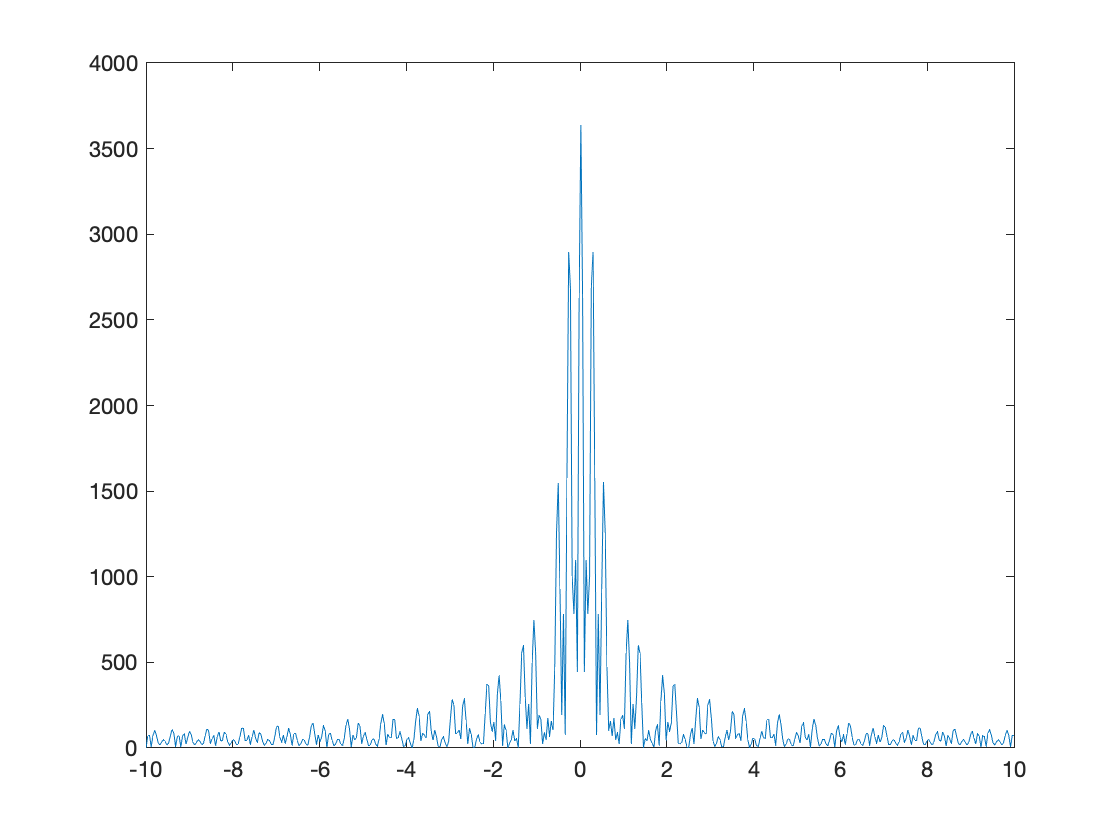

figure;
plot(x,I(length(xx)/2,:));

## Single Circ

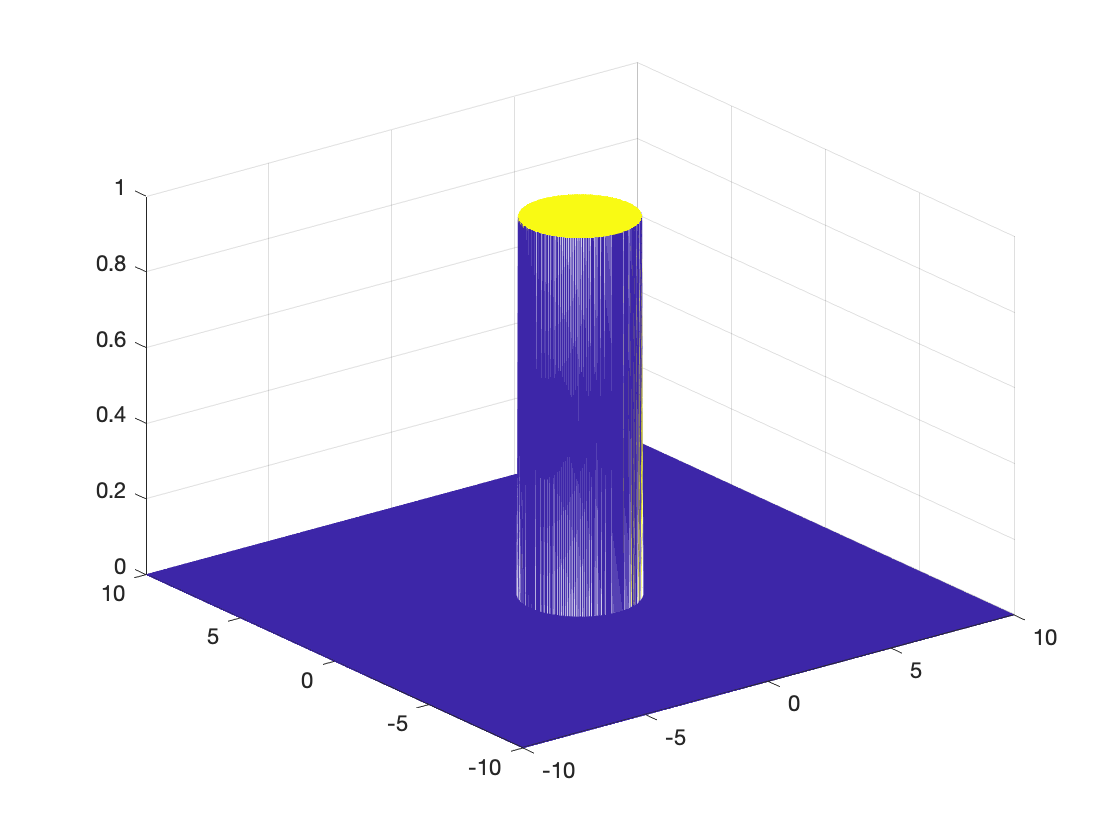

r=2;
circ=sqrt((xx.^2+yy.^2))<=r;
I=abs(fftshift(fft2(circ)));
figure;
mesh(xx,yy,circ);

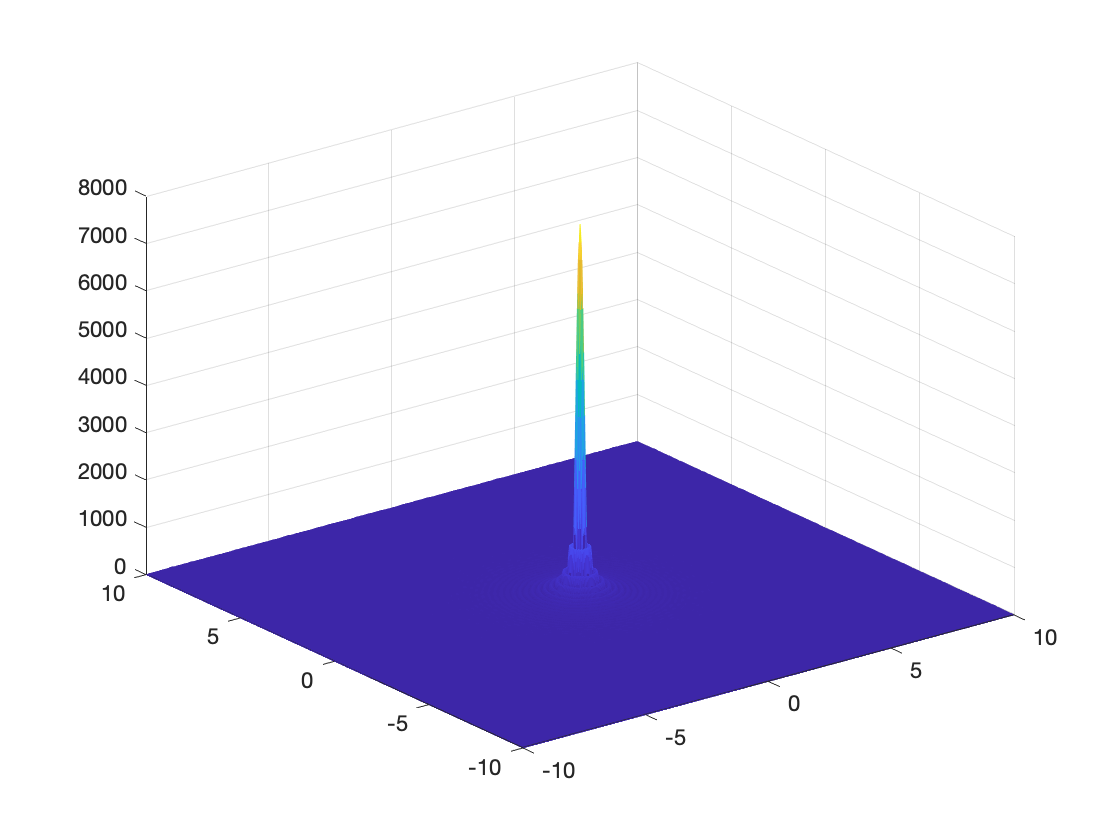

figure;
surf(xx,yy,I,'EdgeColor',"flat",'FaceColor',"flat");

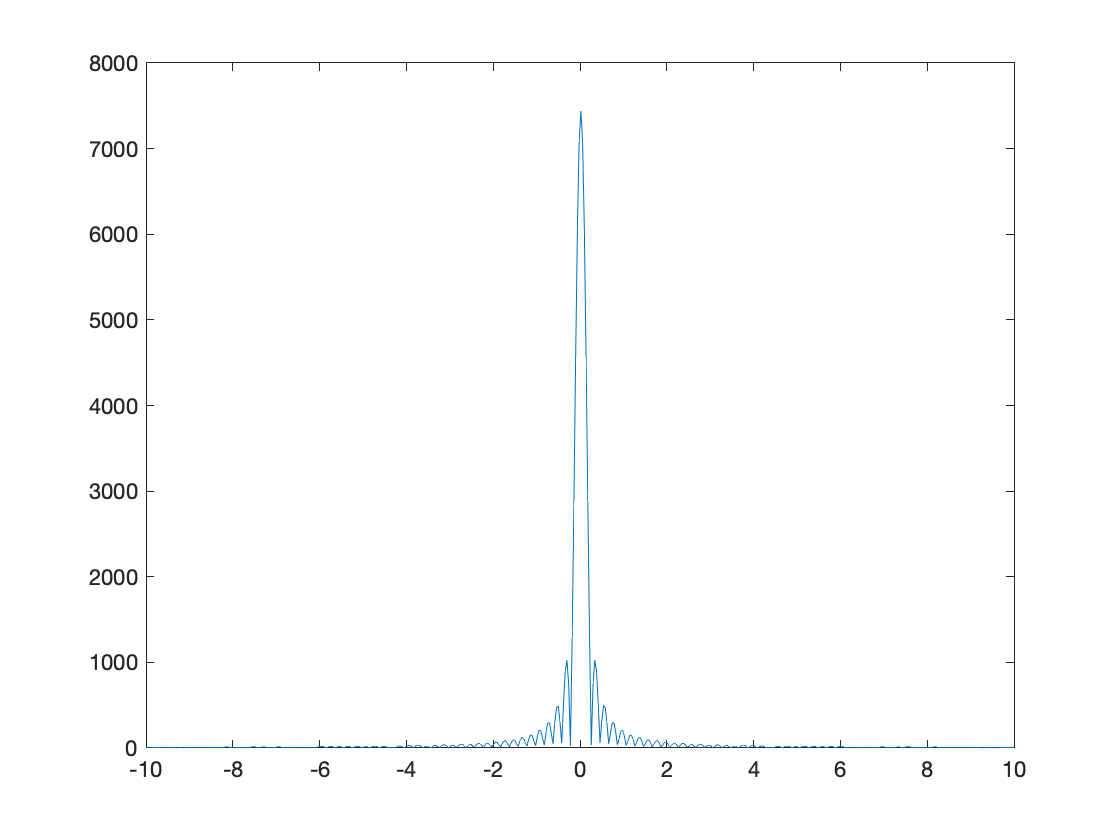

figure;
plot(x,I(length(xx)/2,:));

## Double Circ

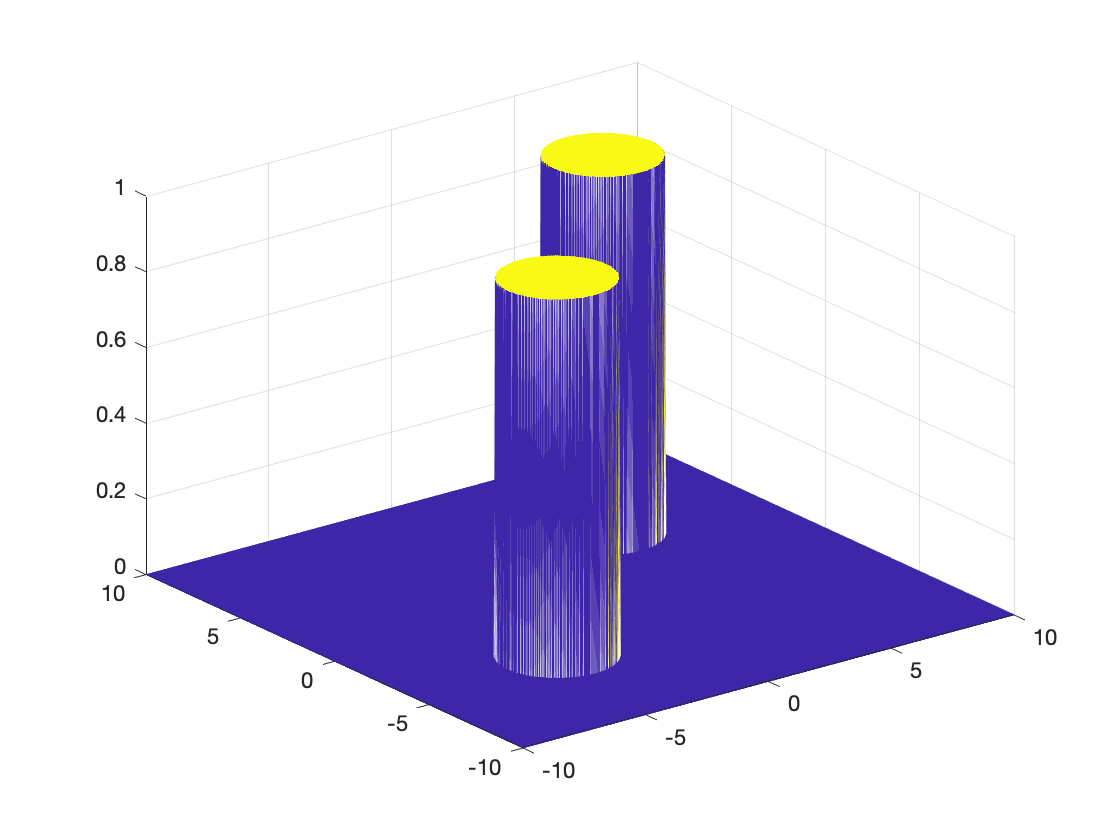

r=2;
d=4;
circ1=sqrt((xx-d).^2+(yy-d).^2)<=r;
circ2=sqrt((xx+d).^2+(yy+d).^2)<=r;
dcirc=circ1|circ2;
I=abs(fftshift(fft2(dcirc)));
figure;
mesh(xx,yy,dcirc);

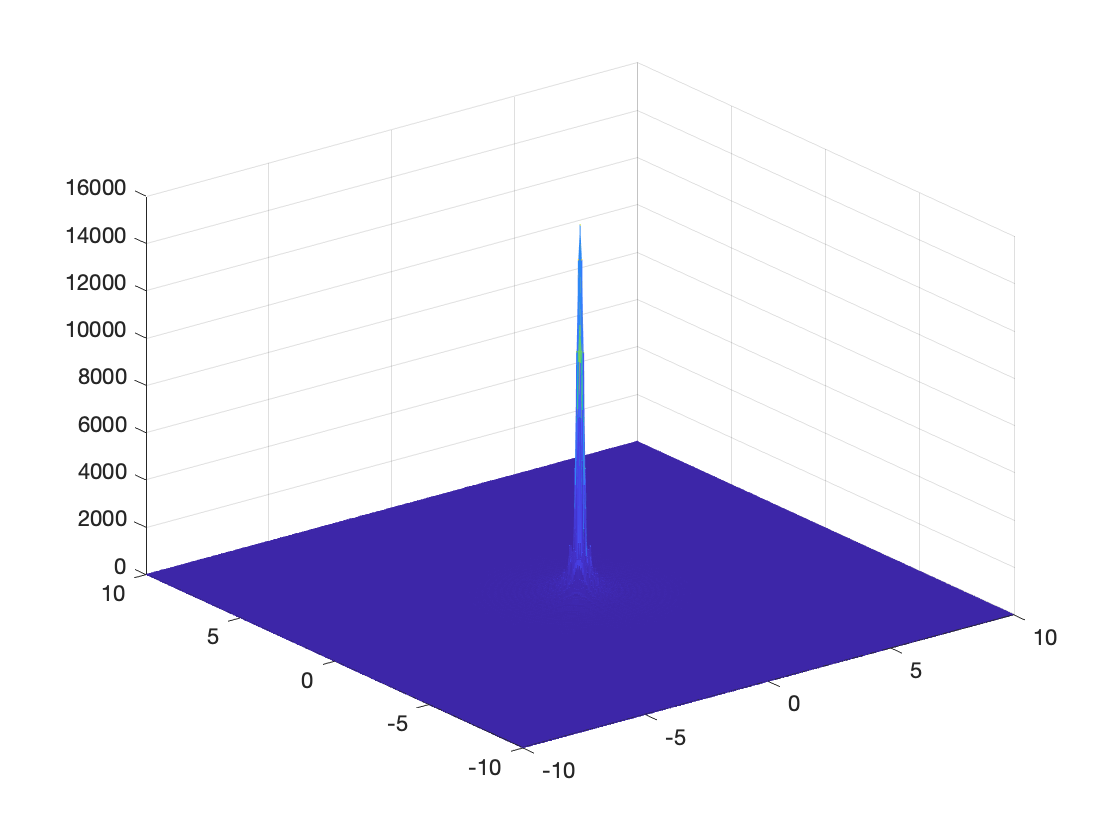

figure;
surf(xx,yy,I,'EdgeColor',"flat",'FaceColor',"flat");

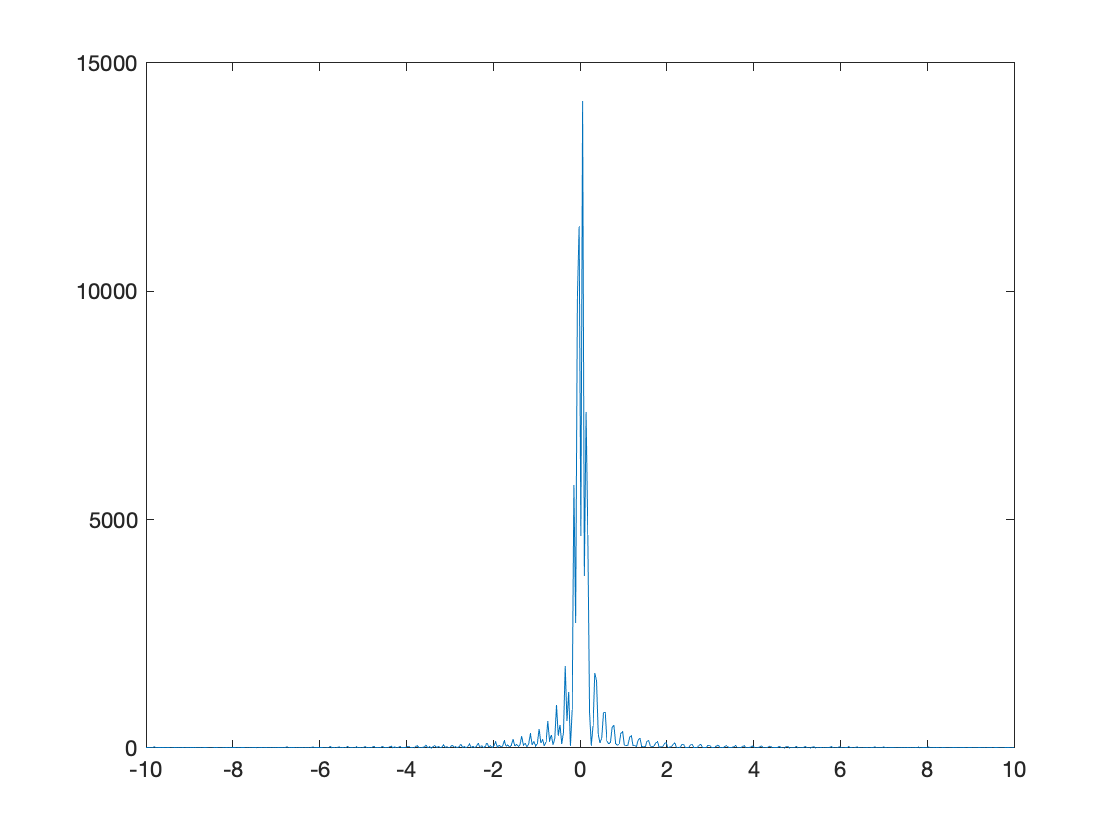

figure;
plot(x,I(length(xx)/2,:));

## Triangle

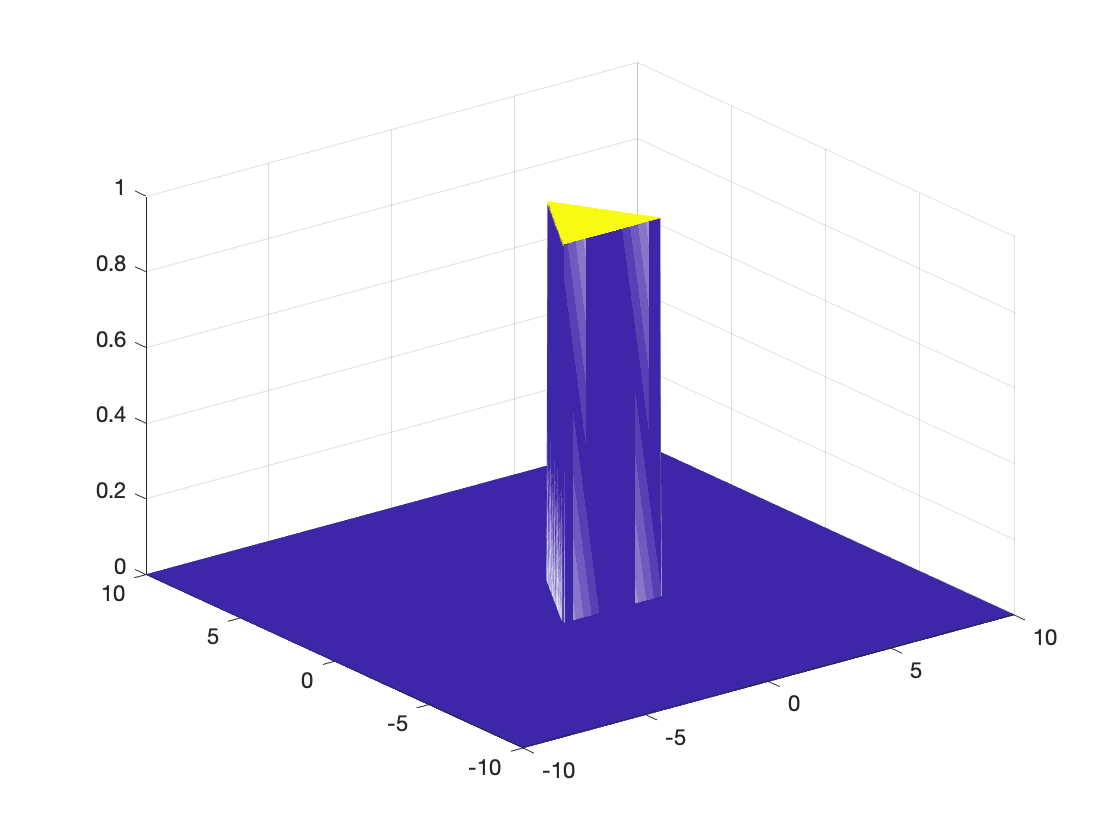

l1=@(x) -sqrt(3).*(x>=-2&x<=2);
l2=@(x) sqrt(3).*(x+1);
l3=@(x) -sqrt(3).*(x-1);

tri=zeros(size(xx));
tri(l1(xx)<=yy&l2(xx)>=yy&l3(xx)>=yy)=1;
I=abs(fftshift(fft2(tri)));
figure;
mesh(xx,yy,tri);

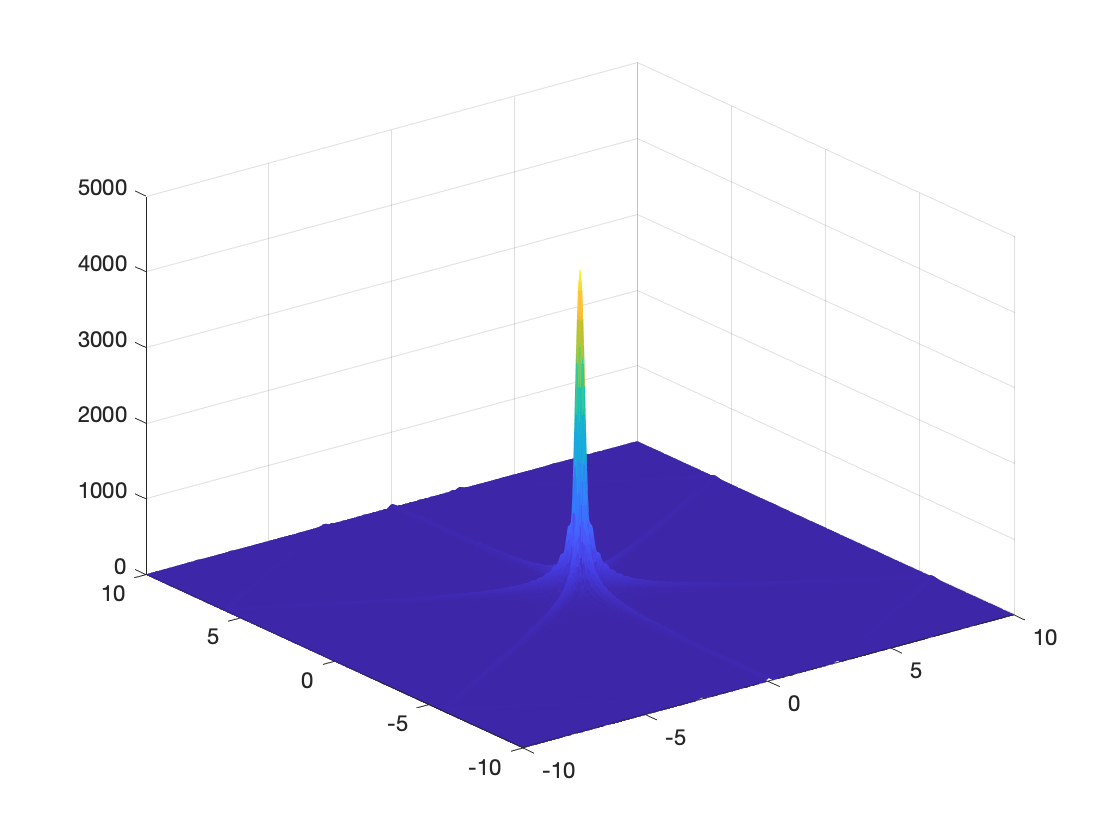

figure;
surf(xx,yy,I,'EdgeColor',"flat",'FaceColor',"flat");

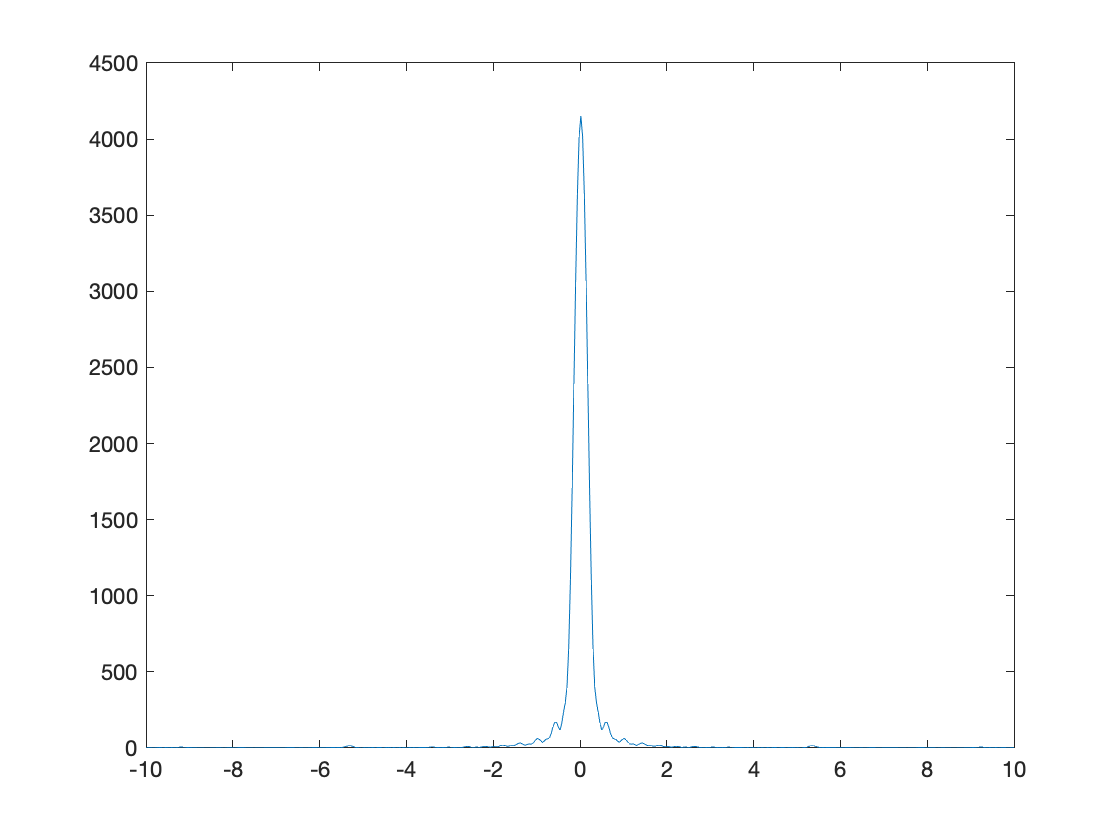

figure;
plot(x,I(length(xx)/2,:));

% clear;clc;